clc;clear;
%更改代码内容
%做一下当前的实验，看两个反射径最后得到的效果如何
%CFO方面的后续内容，如何直接硬估计theta1和theta2
%观察模拟退火是否是有效的，是否能够替代网格搜索算法。
%solve_7equations_function4是硬网格搜索
%问题:这里CFO的估计原理在哪里？为什么可以这么估计？估计效果如何？

% 读取文本文件
% 这一块着实有问题，STS0，需要认真修改一下(AODr45_l0.txt)
% 读取文本文件
filename = '.\AOD_twoway(1.6,2.2,2.2)direct.txt';  % <-- 改成你的文件名
fid = fopen(filename, 'r');
rawData = textscan(fid, '%s', 'Delimiter', '\n');
fclose(fid);

% 获取行内容
lines = rawData{1};


% 初始化存储变量
sn_len = [];
% CIR存储结构
Ipatov_CIR = [];
STS0_CIR = [];
STS1_CIR = [];

% 状态标志
current_mode = '';   % 当前是哪种CIR类型（Ipatov / STS0 / STS1）
inside_CIR_block = false;  % 是否正在读取CIR数据

% 遍历每一行，按规则提取
for i = 1:length(lines)
    line = strtrim(lines{i});
    
    if contains(line, 'Sequence Number')
        tokens = regexp(line, 'Sequence Number[:\s]+(\d+)', 'tokens');
        if ~isempty(tokens)
            sn_len = [sn_len, str2double(tokens{1}{1})];
        else
            disp(['Regex failed to match: ', line]);  % 调试用
        end
    end
        
    
 % 检测 CIR 类型标志
    if contains(line, 'Printing Ipatov CIR')
        current_mode = 'Ipatov';
        inside_CIR_block = false;  % 等待进入“-----------”段

        
    elseif contains(line, 'Printing STS0 CIR')
        current_mode = 'STS0';
        inside_CIR_block = false;  % 等待进入“-----------”段
    elseif contains(line, 'Printing STS1 CIR')
        current_mode = 'STS1';
        inside_CIR_block = false;  % 等待进入“-----------”段 
    end
    
    % 检测 “-----------” 的起始和结束
    if contains(line, '_________________________________')
        inside_CIR_block = ~inside_CIR_block;  % 切换状态
        continue;  % 这行不用处理
    end
    
    % 正在 CIR 数据块内，提取 I, Q
    if inside_CIR_block
        data_tokens = regexp(line, '(-?\d+),(-?\d+)', 'tokens');
        if ~isempty(data_tokens)
            I_val = str2double(data_tokens{1}{1});
            Q_val = str2double(data_tokens{1}{2});
            complex_val = I_val + 1j * Q_val;
            % 根据当前模式放入不同数组
            if strcmp(current_mode, 'Ipatov')
                Ipatov_CIR(end+1, 1) = complex_val;
            elseif strcmp(current_mode, 'STS0')
                STS0_CIR(end+1, 1) = complex_val;
            elseif strcmp(current_mode, 'STS1')
                STS1_CIR(end+1, 1) = complex_val;
            end
        end
    end
end

% 输出到命令行确认
disp(['Sequence Number: ', num2str(sn_len)]);

Sequence Number: 137  138  182  183  227  228   16   17   61   62  106  107  151  152  196  197  241  242   30   31   75   76  120  121  165  166  210  211  255    0   44   45   89   90  134  135  179  180  224  225   13   14   58   59  103  104  148  149  193  194  238  239   27   28   72   73  117  118  162  163  207  208  252  253   41   42   86   87  131  132  176  177  221  222   10   11   55   56  100  101  145  146  190  191  235  236   24   25   69   70  114  115  159  160  204  205  249  250   38   39   83   84  128  129  173  174  218  219    7    8   52   53   97   98  142  143  187  188  232  233   21   22   66   67  111  112  156  157  201  202  246  247   35   36   80   81  125  126  170  171  215  216    4    5   49   50   94   95  139  140  184  185  229  230   18   19   63   64  108  109  153  154  198  199  243  244   32   33   77   78  122  123  167  168  212  213    1    2   46   47   91   92  136  137  181  182  226  227   15   16   60   61  105  106  150  151  195

% 修复 sn_len 中 255->0 的问题
for k = 2:length(sn_len)
    if sn_len(k) == 0 && sn_len(k-1) == 255
        sn_len(k) = 256;   % 把0改成256
    end
end

% --- 后续 reshape 保持不变 ---
packets_num = length(STS0_CIR)/512;
STS0_CIR = reshape(STS0_CIR(1:512 * packets_num), 512, packets_num).';
STS1_CIR = reshape(STS1_CIR(1:512 * packets_num), 512, packets_num).';

% --- 包顺序修复 ---
i = 1;
while i < packets_num
    if mod(sn_len(i),2) == 1   % 如果当前位置是奇数包
        % --- 交换 STS0 ---
        temp = STS0_CIR(i, :);
        STS0_CIR(i, :) = STS0_CIR(i+1, :);
        STS0_CIR(i+1, :) = temp;

        % --- 交换 STS1 ---
        temp = STS1_CIR(i, :);
        STS1_CIR(i, :) = STS1_CIR(i+1, :);
        STS1_CIR(i+1, :) = temp;

        % --- 交换 sn_len ---
        temp = sn_len(i);
        sn_len(i) = sn_len(i+1);
        sn_len(i+1) = temp;
    end
    i = i + 2;
end


% --- 确保偶数个数据包 ---
if mod(packets_num, 2) ~= 0
    STS0_CIR(end, :) = [];
    STS1_CIR(end, :) = [];
    sn_len(end) = [];   % 同时删除掉最后一个 Sequence Number
    packets_num = packets_num - 1;
end

sn_len

sn_len =    138   137   182   183   228   227    16    17    62    61   106   107   152   151   196   197   242   241    30    31    76    75   120   121   166   165   210   211   256   255    44    45    90    89   134   135   180   179   224   225    14    13    58    59   104   103   148   149   194   193


c =physconst("LightSpeed"); % wavelength (assume)
lambda=c/7.9872e9;
antennaSpacing = lambda * 0.5;
% antennaSpacing = 0.0182;
% frequency=4992.8e6;
frequency=7.9872e9;
phase_offset = 0.17;
% -0.67, -0.88, -1.01， -0.72
pdoa_values_main = [];
degree_values_main = [];

pdoa_values_secondary = [];
degree_values_secondary = [];

peaks_index_STS0 = [];
peaks_index_STS1 = [];
pdoa_values_ref1 = [];
pdoa_values_ref2 = [];
degree_values_ref1 = [];
degree_values_ref2 = [];

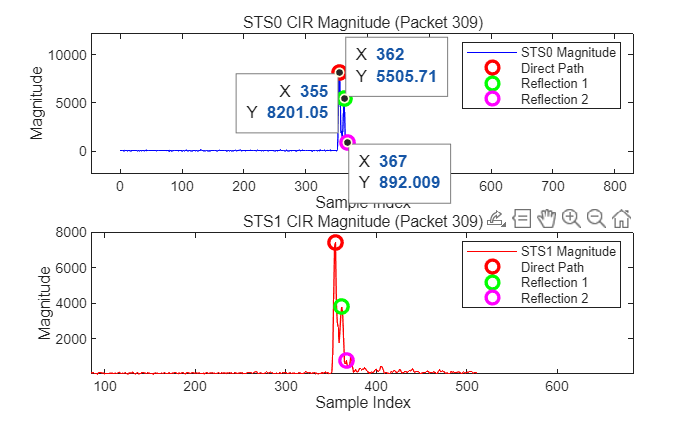

for i = 1:packets_num
    % 取出第 i 组 CIR 数据
    STS0_data = STS0_CIR(i,:);  
    STS1_data = STS1_CIR(i,:);
    
    % 幅度
    STS0_magnitude = abs(STS0_data);
    STS1_magnitude = abs(STS1_data);

    threshold = 0.1;            % 阈值
    min_peak_distance = 3;      % 峰值之间最少间隔 3 个采样点
    
    % 找峰值
    [peaks_STS0, locs_STS0] = findpeaks(STS0_magnitude, 'MinPeakHeight', threshold * max(STS0_magnitude), 'MinPeakDistance', min_peak_distance);
    [peaks_STS1, locs_STS1] = findpeaks(STS1_magnitude, 'MinPeakHeight', threshold * max(STS1_magnitude), 'MinPeakDistance', min_peak_distance);

    % 至少需要 3 个峰
    if length(locs_STS0) < 3 || length(locs_STS1) < 3
        continue; 
    end

    % 主峰 + 两个反射峰（假设 findpeaks 返回按位置排序）
    peak_index1_STS0 = locs_STS0(1); % 直射
    peak_index2_STS0 = locs_STS0(2); % 反射1
    peak_index3_STS0 = locs_STS0(3); % 反射2
    
    peak_index1_STS1 = locs_STS1(1);
    peak_index2_STS1 = locs_STS1(2);
    peak_index3_STS1 = locs_STS1(3);

    % 简单的对齐检查
    if abs(peak_index1_STS1 - peak_index1_STS0) >= 3 || ...
       abs(peak_index2_STS1 - peak_index2_STS0) >= 3 || ...
       abs(peak_index3_STS1 - peak_index3_STS0) >= 3
        continue;
    end
    
    % 保存索引
    peaks_index_STS0 = [peaks_index_STS0; peak_index1_STS0, peak_index2_STS0, peak_index3_STS0];
    peaks_index_STS1 = [peaks_index_STS1; peak_index1_STS1, peak_index2_STS1, peak_index3_STS1];
    
    %% ---- 相位差计算 (三个峰) ----
    % 主峰 (直射)
    STS0_phase_main = angle(STS0_data(peak_index1_STS0));
    STS1_phase_main = angle(STS1_data(peak_index1_STS1));
    phase_difference_main = STS1_phase_main - STS0_phase_main - phase_offset;
    phase_difference_main = mod(phase_difference_main + pi, 2*pi) - pi;
    theta_radians_main = asin(phase_difference_main * c / (2 * pi * antennaSpacing * frequency));
    theta_degrees_main = rad2deg(theta_radians_main);

    pdoa_values_main(1,end+1) = phase_difference_main;
    degree_values_main(1,end+1) = theta_degrees_main;
    
    % 次强峰 (反射1)
    STS0_phase_ref1 = angle(STS0_data(peak_index2_STS0));
    STS1_phase_ref1 = angle(STS1_data(peak_index2_STS1));
    phase_difference_ref1 = STS1_phase_ref1 - STS0_phase_ref1 - phase_offset;
    phase_difference_ref1 = mod(phase_difference_ref1 + pi, 2*pi) - pi;
    theta_radians_ref1 = asin(phase_difference_ref1 * c / (2 * pi * antennaSpacing * frequency));
    theta_degrees_ref1 = rad2deg(theta_radians_ref1);

    pdoa_values_ref1(1,end+1) = phase_difference_ref1;
    degree_values_ref1(1,end+1) = theta_degrees_ref1;

    % 第三峰 (反射2)
    STS0_phase_ref2 = angle(STS0_data(peak_index3_STS0));
    STS1_phase_ref2 = angle(STS1_data(peak_index3_STS1));
    phase_difference_ref2 = STS1_phase_ref2 - STS0_phase_ref2 - phase_offset;
    phase_difference_ref2 = mod(phase_difference_ref2 + pi, 2*pi) - pi;
    theta_radians_ref2 = asin(phase_difference_ref2 * c / (2 * pi * antennaSpacing * frequency));
    theta_degrees_ref2 = rad2deg(theta_radians_ref2);

    pdoa_values_ref2(1,end+1) = phase_difference_ref2;
    degree_values_ref2(1,end+1) = theta_degrees_ref2;

    %% ---- 画图并标记峰值 ----
    figure(100);
    clf; % 清空画布

    subplot(2,1,1);
    plot(STS0_magnitude, 'b');
    hold on;
    plot(peak_index1_STS0, STS0_magnitude(peak_index1_STS0), 'ro', 'MarkerSize', 8, 'LineWidth', 2); % 主峰
    plot(peak_index2_STS0, STS0_magnitude(peak_index2_STS0), 'go', 'MarkerSize', 8, 'LineWidth', 2); % 反射1
    plot(peak_index3_STS0, STS0_magnitude(peak_index3_STS0), 'mo', 'MarkerSize', 8, 'LineWidth', 2); % 反射2
    hold off;
    title(['STS0 CIR Magnitude (Packet ', num2str(i), ')']);
    xlabel('Sample Index');
    ylabel('Magnitude');
    legend('STS0 Magnitude', 'Direct Path', 'Reflection 1', 'Reflection 2');

    subplot(2,1,2);
    plot(STS1_magnitude, 'r');
    hold on;
    plot(peak_index1_STS1, STS1_magnitude(peak_index1_STS1), 'ro', 'MarkerSize', 8, 'LineWidth', 2); 
    plot(peak_index2_STS1, STS1_magnitude(peak_index2_STS1), 'go', 'MarkerSize', 8, 'LineWidth', 2); 
    plot(peak_index3_STS1, STS1_magnitude(peak_index3_STS1), 'mo', 'MarkerSize', 8, 'LineWidth', 2); 
    hold off;
    title(['STS1 CIR Magnitude (Packet ', num2str(i), ')']);
    xlabel('Sample Index');
    ylabel('Magnitude');
    legend('STS1 Magnitude', 'Direct Path', 'Reflection 1', 'Reflection 2');

end

%% ----------------- 循环后统一处理 -----------------
% 定义异常值滤波函数（3σ原则）
filter_outliers = @(x) x(abs(x - mean(x)) <= 3*std(x));

pdoa_values_ref1 = abs(pdoa_values_ref1);
degree_values_ref1 = abs(degree_values_ref1);

% 滤波后的数据
pdoa_main_filt = filter_outliers(pdoa_values_main);
pdoa_ref1_filt = filter_outliers(pdoa_values_ref1);
pdoa_ref2_filt = filter_outliers(pdoa_values_ref2);

degree_main_filt = filter_outliers(degree_values_main);
degree_ref1_filt = filter_outliers(degree_values_ref1);
degree_ref2_filt = filter_outliers(degree_values_ref2);

% 计算均值和标准差
mean_pdoa = [mean(pdoa_main_filt), mean(pdoa_ref1_filt), mean(pdoa_ref2_filt)];
std_pdoa  = [std(pdoa_main_filt),  std(pdoa_ref1_filt),  std(pdoa_ref2_filt)];

mean_degree = [mean(degree_main_filt), mean(degree_ref1_filt), mean(degree_ref2_filt)];
std_degree  = [std(degree_main_filt),  std(degree_ref1_filt),  std(degree_ref2_filt)];

% 打印结果
disp('==== PDOA Mean ± Std ====');

==== PDOA Mean ± Std ====


fprintf('Direct: %.4f ± %.4f rad\n', mean_pdoa(1), std_pdoa(1));

Direct: 0.0290 ± 0.1052 rad


fprintf('Ref1  : %.4f ± %.4f rad\n', mean_pdoa(2), std_pdoa(2));

Ref1  : 1.6759 ± 0.2141 rad


fprintf('Ref2  : %.4f ± %.4f rad\n', mean_pdoa(3), std_pdoa(3));

Ref2  : 2.2750 ± 0.2978 rad



disp('==== AOA Mean ± Std ====');

==== AOA Mean ± Std ====


fprintf('Direct: %.2f ± %.2f deg\n', mean_degree(1), std_degree(1));

Direct: 0.53 ± 1.92 deg


fprintf('Ref1  : %.2f ± %.2f deg\n', mean_degree(2), std_degree(2));

Ref1  : 32.36 ± 4.70 deg


fprintf('Ref2  : %.2f ± %.2f deg\n', mean_degree(3), std_degree(3));

Ref2  : 47.20 ± 9.03 deg


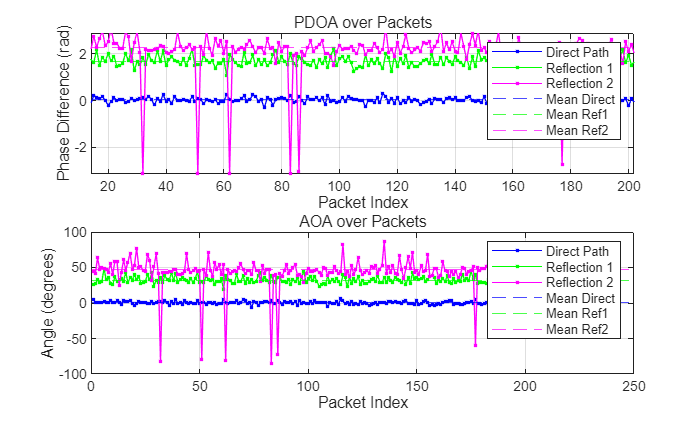


%% ----------------- 绘图 -----------------
figure;

% PDOA
subplot(2,1,1);
plot(pdoa_values_main, 'b.-'); hold on;
plot(pdoa_values_ref1, 'g.-');
plot(pdoa_values_ref2, 'm.-');
yline(mean_pdoa(1), '--b'); % 均值线
yline(mean_pdoa(2), '--g');
yline(mean_pdoa(3), '--m');
title('PDOA over Packets');
xlabel('Packet Index'); ylabel('Phase Difference (rad)');
legend('Direct Path','Reflection 1','Reflection 2','Mean Direct','Mean Ref1','Mean Ref2');
grid on;

% AOA
subplot(2,1,2);
plot(degree_values_main, 'b.-'); hold on;
plot(degree_values_ref1, 'g.-');
plot(degree_values_ref2, 'm.-');
yline(mean_degree(1), '--b');
yline(mean_degree(2), '--g');
yline(mean_degree(3), '--m');
title('AOA over Packets');
xlabel('Packet Index'); ylabel('Angle (degrees)');
legend('Direct Path','Reflection 1','Reflection 2','Mean Direct','Mean Ref1','Mean Ref2');
grid on;

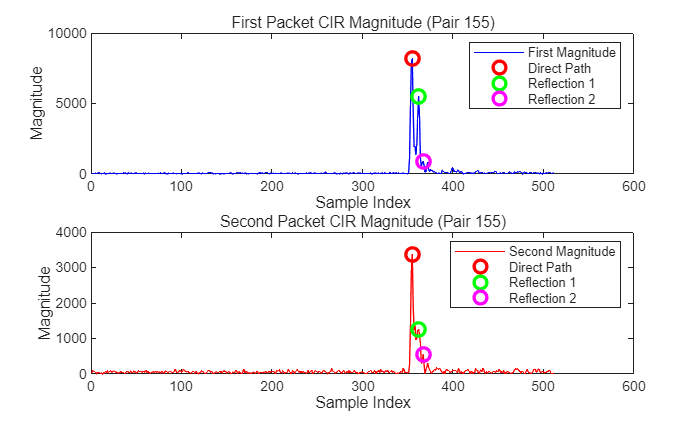

first_packet_cir  = STS0_CIR(1:2:end, :);  % 奇数行
second_packet_cir = STS0_CIR(2:2:end, :);  % 偶数行

%这里估计的main,ref1,ref2在到处乱飞
aod_pdoa_values_main = [];
aod_degree_values_main = [];

aod_pdoa_values_ref1 = [];
aod_degree_values_ref1 = [];

aod_pdoa_values_ref2 = [];
aod_degree_values_ref2 = [];

peaks_index_first = [];
peaks_index_second = [];

num_pairs = size(first_packet_cir, 1);  % 每组两个packet

% 视频初始化
video_filename = '.\double_reflection.avi';
v = VideoWriter(video_filename);  % 默认是 Motion JPEG AVI
v.FrameRate = 5;  % 可根据需要调整帧率
open(v);

for i = 1:num_pairs
    first_data = first_packet_cir(i, :);
    second_data = second_packet_cir(i, :);
    
    % 幅度
    first_magnitude = abs(first_data);
    second_magnitude = abs(second_data);

    threshold = 0.1;
    min_peak_distance = 3;
    
    [peaks_first, locs_first] = findpeaks(first_magnitude, 'MinPeakHeight', threshold * max(first_magnitude), 'MinPeakDistance', min_peak_distance);
    [peaks_second, locs_second] = findpeaks(second_magnitude, 'MinPeakHeight', threshold * max(second_magnitude), 'MinPeakDistance', min_peak_distance);

    % 需要至少 3 个峰
    if length(locs_first) < 3 || length(locs_second) < 3
        continue; % 跳过不满足条件的帧
    end

    % 取三个峰
    peak_index1_first = locs_first(1); % 直射
    peak_index2_first = locs_first(2); % 反射1
    peak_index3_first = locs_first(3); % 反射2

    peak_index1_second = locs_second(1);
    peak_index2_second = locs_second(2);
    peak_index3_second = locs_second(3);

    peaks_index_first = [peaks_index_first; peak_index1_first, peak_index2_first, peak_index3_first];
    peaks_index_second = [peaks_index_second; peak_index1_second, peak_index2_second, peak_index3_second];

    %% ---- 相位差计算 ----
    % 主峰 (直射)
    phase_first_main = angle(first_data(peak_index1_first));
    phase_second_main = angle(second_data(peak_index1_second));
    phase_diff_main = phase_second_main - phase_first_main;
    phase_diff_main = mod(phase_diff_main + pi, 2*pi) - pi;
    theta_rad_main = asin(phase_diff_main * c / (2 * pi * antennaSpacing * frequency));
    theta_deg_main = rad2deg(theta_rad_main);

    aod_pdoa_values_main(end+1) = phase_diff_main;
    aod_degree_values_main(end+1) = theta_deg_main;


    % 反射1
    phase_first_ref1 = angle(first_data(peak_index2_first));
    phase_second_ref1 = angle(second_data(peak_index2_second));
    phase_diff_ref1 = phase_second_ref1 - phase_first_ref1;
    phase_diff_ref1 = mod(phase_diff_ref1 + pi, 2*pi) - pi;
    theta_rad_ref1 = asin(phase_diff_ref1 * c / (2 * pi * antennaSpacing * frequency));
    theta_deg_ref1 = rad2deg(theta_rad_ref1);

    aod_pdoa_values_ref1(end+1) = phase_diff_ref1;
    aod_degree_values_ref1(end+1) = theta_deg_ref1;

    % 反射2
    phase_first_ref2 = angle(first_data(peak_index3_first));
    phase_second_ref2 = angle(second_data(peak_index3_second));
    phase_diff_ref2 = phase_second_ref2 - phase_first_ref2;
    phase_diff_ref2 = mod(phase_diff_ref2 + pi, 2*pi) - pi;
    theta_rad_ref2 = asin(phase_diff_ref2 * c / (2 * pi * antennaSpacing * frequency));
    theta_deg_ref2 = rad2deg(theta_rad_ref2);

    aod_pdoa_values_ref2(end+1) = phase_diff_ref2;
    aod_degree_values_ref2(end+1) = theta_deg_ref2;
    
    
 
    %fprintf("There are main:%d ref1:%d ref2:%d",theta_deg_main,theta_deg_ref1,theta_deg_ref1);
    %% ---- 画图 ----

    figure(100);    
    clf; 
    subplot(2,1,1);
    plot(first_magnitude, 'b');
    hold on;
    plot(peak_index1_first, first_magnitude(peak_index1_first), 'ro', 'MarkerSize', 8, 'LineWidth', 2);
    plot(peak_index2_first, first_magnitude(peak_index2_first), 'go', 'MarkerSize', 8, 'LineWidth', 2);
    plot(peak_index3_first, first_magnitude(peak_index3_first), 'mo', 'MarkerSize', 8, 'LineWidth', 2);
    title(['First Packet CIR Magnitude (Pair ', num2str(i), ')']);
    xlabel('Sample Index'); ylabel('Magnitude');
    legend('First Magnitude', 'Direct Path', 'Reflection 1', 'Reflection 2');

    subplot(2,1,2);
    plot(second_magnitude, 'r');
    hold on;
    plot(peak_index1_second, second_magnitude(peak_index1_second), 'ro', 'MarkerSize', 8, 'LineWidth', 2);
    plot(peak_index2_second, second_magnitude(peak_index2_second), 'go', 'MarkerSize', 8, 'LineWidth', 2);
    plot(peak_index3_second, second_magnitude(peak_index3_second), 'mo', 'MarkerSize', 8, 'LineWidth', 2);
    title(['Second Packet CIR Magnitude (Pair ', num2str(i), ')']);
    xlabel('Sample Index'); ylabel('Magnitude');
    legend('Second Magnitude', 'Direct Path', 'Reflection 1', 'Reflection 2');

        % % 把当前帧写入视频
    frame = getframe(gcf);
    writeVideo(v, frame);

end


% 关闭视频
close(v);
disp(['视频已保存为: ', video_filename]);

视频已保存为: .\double_reflection.avi


peak_index3_second-peak_index3_first

ans = 0

aod_pdoa_diff1 = aod_pdoa_values_ref1 - aod_pdoa_values_main;
aod_pdoa_diff2 = aod_pdoa_values_ref2 - aod_pdoa_values_main;
aod_pdoa_diff1 = mod(aod_pdoa_diff1+pi,2*pi) - pi;
aod_pdoa_diff2 = mod(aod_pdoa_diff2+pi,2*pi) - pi;

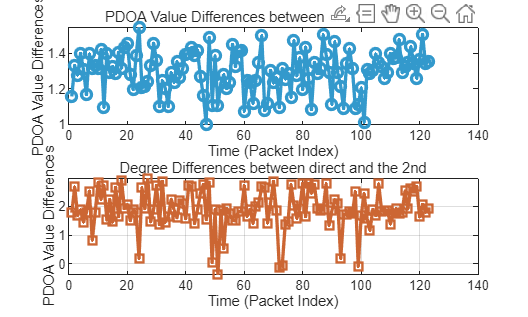

time = 1:length(aod_pdoa_values_main);
figure;

subplot(2,1,1);
plot(time, aod_pdoa_diff1, '-o', 'LineWidth', 2, 'Color', [0.2 0.6 0.8]);
title('PDOA Value Differences between direct and the 1st');
xlabel('Time (Packet Index)');
ylabel('PDOA Value Differences');

subplot(2,1,2);
plot(time, aod_pdoa_diff2, '-s', 'LineWidth', 2, 'Color', [0.8 0.4 0.2]);
title('Degree Differences between direct and the 2nd');
xlabel('Time (Packet Index)');
ylabel('PDOA Value Differences');
grid on;


%% ========== 去除异常值（基于3σ原则） ==========

% --- 对 aod_pdoa_diff1 ---
mean1 = mean(aod_pdoa_diff1);
std1 = std(aod_pdoa_diff1);

valid_idx1 = abs(aod_pdoa_diff1 - mean1) <= 3*std1;  % 保留在3σ以内的数据
filtered_diff1 = aod_pdoa_diff1(valid_idx1);

% --- 对 aod_pdoa_diff2 ---
mean2 = mean(aod_pdoa_diff2);
std2 = std(aod_pdoa_diff2);

valid_idx2 = abs(aod_pdoa_diff2 - mean2) <= 3*std2;
filtered_diff2 = aod_pdoa_diff2(valid_idx2);

%% ========== 计算滤除异常值后的统计量 ==========

% 1st difference
mean_filtered1 = mean(filtered_diff1);
std_filtered1  = std(filtered_diff1);
fprintf('Diff1 PDOA 平均值: %.2f\n', mean_filtered1);

Diff1 PDOA 平均值: 1.29


fprintf('Diff1 PDOA 标准差: %.2f\n', std_filtered1);

Diff1 PDOA 标准差: 0.12



% 2nd difference
mean_filtered2 = mean(filtered_diff2);
std_filtered2  = std(filtered_diff2);
fprintf('Diff2 PDOA 平均值: %.2f\n', mean_filtered2);

Diff2 PDOA 平均值: 1.91


fprintf('Diff2 PDOA 标准差: %.2f\n', std_filtered2);

Diff2 PDOA 标准差: 0.65


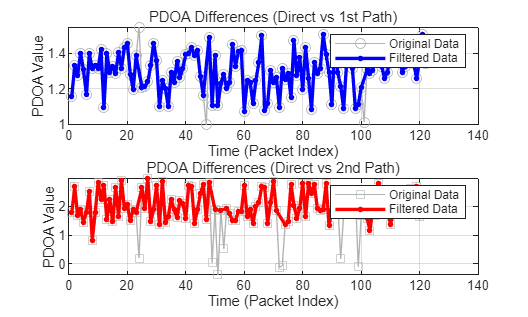

time = 1:length(aod_pdoa_values_main);

%% ========== 去除异常值（基于3σ原则） ==========
% --- 对 aod_pdoa_diff1 ---
mean1 = mean(aod_pdoa_diff1);
std1 = std(aod_pdoa_diff1);
valid_idx1 = abs(aod_pdoa_diff1 - mean1) <= 2*std1;  
filtered_diff1 = aod_pdoa_diff1(valid_idx1);
time_filtered1 = time(valid_idx1);

% --- 对 aod_pdoa_diff2 ---
mean2 = mean(aod_pdoa_diff2);
std2 = std(aod_pdoa_diff2);
valid_idx2 = abs(aod_pdoa_diff2 - mean2) <= 2*std2;
filtered_diff2 = aod_pdoa_diff2(valid_idx2);
time_filtered2 = time(valid_idx2);

%% ========== 画图 ==========
figure;

subplot(2,1,1);
plot(time, aod_pdoa_diff1, 'o-', 'Color', [0.7 0.7 0.7]); hold on;
plot(time_filtered1, filtered_diff1, 'b.-', 'LineWidth', 2, 'MarkerSize', 10);
title('PDOA Differences (Direct vs 1st Path)');
xlabel('Time (Packet Index)');
ylabel('PDOA Value');
legend('Original Data','Filtered Data');
grid on;

subplot(2,1,2);
plot(time, aod_pdoa_diff2, 's-', 'Color', [0.7 0.7 0.7]); hold on;
plot(time_filtered2, filtered_diff2, 'r.-', 'LineWidth', 2, 'MarkerSize', 10);
title('PDOA Differences (Direct vs 2nd Path)');
xlabel('Time (Packet Index)');
ylabel('PDOA Value');
legend('Original Data','Filtered Data');
grid on;


%% ========== 输出滤除后的统计量 ==========
mean_filtered1 = mean(filtered_diff1);
std_filtered1  = std(filtered_diff1);
fprintf('Diff1 PDOA 平均值: %.2f\n', mean_filtered1);

Diff1 PDOA 平均值: 1.30


fprintf('Diff1 PDOA 标准差: %.2f\n', std_filtered1);

Diff1 PDOA 标准差: 0.11



mean_filtered2 = mean(filtered_diff2);
std_filtered2  = std(filtered_diff2);
fprintf('Diff2 PDOA 平均值: %.2f\n', mean_filtered2);

Diff2 PDOA 平均值: 2.02


fprintf('Diff2 PDOA 标准差: %.2f\n', std_filtered2);

Diff2 PDOA 标准差: 0.49


aod_theta_diff1  = lambda * aod_pdoa_diff1 / (2*pi*antennaSpacing);
aod_theta_diff2  = lambda * aod_pdoa_diff2 / (2*pi*antennaSpacing);
%fprintf("theta_diff1:%d theta_diff2:%d\n",aod_theta_diff1,aod_theta_diff2);
aod_theta_diff1

aod_theta_diff1 =     0.3682    0.4236    0.4064    0.4453    0.4160    0.3712    0.4441    0.4182    0.4227    0.4182    0.4522    0.3480    0.4456    0.4107    0.4221    0.4089    0.4472    0.4186    0.4562    0.4630    0.4082    0.3800    0.4405    0.4924    0.3842    0.3852    0.3941    0.4231    0.4636    0.4326    0.3500    0.3963    0.3826    0.3500    0.4109    0.3935    0.4309    0.4018    0.4184    0.4437    0.4456    0.4558    0.4407    0.4511    0.4031    0.3705    0.3170    0.4740    0.3527    0.4405


aod_theta_diff2

aod_theta_diff2 =     0.5661    0.8508    0.5360    0.5971    0.4605    0.5683    0.8057    0.2619    0.5626    0.9031    0.7107    0.8723    0.4850    0.7145    0.4628    0.8483    0.5244    0.9248    0.6124    0.6547    0.4749    0.5989    0.5654    0.0589    0.8408    0.6078    0.9504    0.4635    0.6035    0.8705    0.4321    0.9131    0.4589    0.5222    0.7168    0.5957    0.5074    0.6976    0.6648    0.4981    0.8716    0.8519    0.4473    0.5960    0.7780    0.8790    0.4885    0.9052    0.0098    0.6007


former_diff1 = aod_theta_diff1(1:20);
former_diff2 = aod_theta_diff2(1:20);
former_diff1

former_diff1 =     0.3682    0.4236    0.4064    0.4453    0.4160    0.3712    0.4441    0.4182    0.4227    0.4182    0.4522    0.3480    0.4456    0.4107    0.4221    0.4089    0.4472    0.4186    0.4562    0.4630


former_diff2

former_diff2 =     0.5661    0.8508    0.5360    0.5971    0.4605    0.5683    0.8057    0.2619    0.5626    0.9031    0.7107    0.8723    0.4850    0.7145    0.4628    0.8483    0.5244    0.9248    0.6124    0.6547


aod_mean_sin1 = mean(former_diff1)

aod_mean_sin1 = 0.4203

aod_mean_sin2 = mean(former_diff2)

aod_mean_sin2 = 0.6461


%为什么前面都是正数，后面就变成有正有负的了


